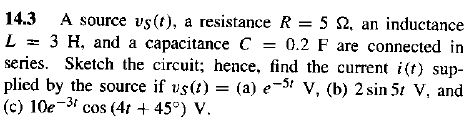

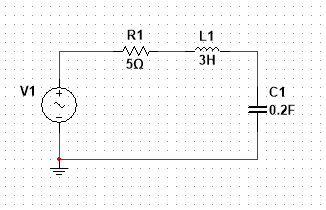

primero convertirmos las impedancias en terminos de la variable compleja s

clc, clear, close all
format short g
syms s t I

r = 5;
l = 3;
c = 0.2;

zr = 5

zr =      5


zl = l*s

$$zl = 3\,s$$

zc = 1/(s*c) 

$$zc = \frac{5}{s}$$

Teniendo todo en terminos de s, aplicamos LTK

**a) **en este caso solo tenemos parte real de s

vf = exp(-5*t); %[V]
If = solve(zr*I + zl*I + zc*I == vf,I) %[A]

$$If = \frac{{\mathrm{e}}^{-5\,t}}{3\,s+\frac{5}{s}+5}$$

s = -5; %frecuencia compleja
If = vf/((3*s)+(5/s)+(5)) %[A]

$$If = -\frac{{\mathrm{e}}^{-5\,t}}{11}$$

**b) **para este caso solo tenemos parte imaginaria de s

expresamos la tension de la fuente en forma cosenoisal

vf = 2*cos(5*t-90) %[V]

$$vf = 2\,\cos\left(5\,t-90\right)$$

expresamos la tension de la fuente como un numero complejo

vm = 2;
va = -90;
vf = vm*(cosd(va)+j*sind(va))

vf =             0 -          2i


If = solve(zr*I + zl*I + zc*I == vf,I) %[A]

$$If = -\frac{2\,\mathrm{i}}{3\,s+\frac{5}{s}+5}$$

s = 5*j %frecuencia compleja

s =             0 +          5i


If = vf/((3*s)+(5/s)+(5)) %[A]

If =       -0.1267 -   0.045249i


If = [abs(If) angle(If)*180/pi] %[A]

If =       0.13453      -160.35


Verificamos en el simulador

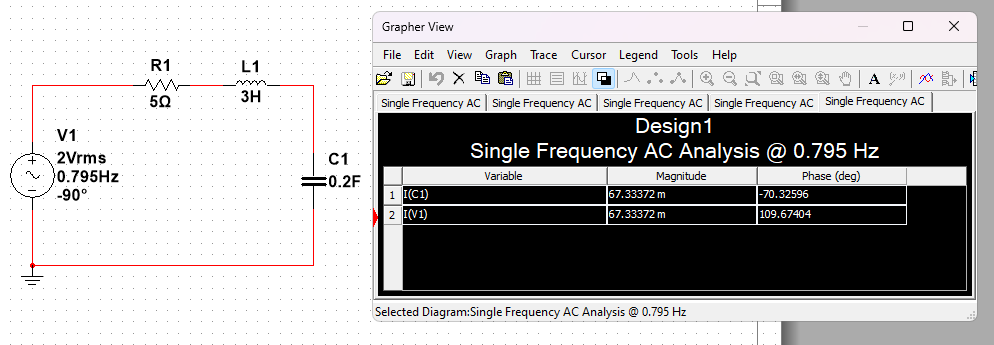

**c) **en este caso tenemos de todo

vf = 10*exp(-3*t)*cos(4*t+45) %[V]

$$vf = 10\,{\mathrm{e}}^{-3\,t}\,\cos\left(4\,t+45\right)$$

vm = 10;
va = 45;
vf = vm*(cosd(va)+j*sind(va)) %Expresado en numero complejo

vf =        7.0711 +     7.0711i


If = solve(zr*I + zl*I + zc*I == vf,I) %[A]

$$If = \frac{\sqrt{2}\,\left(5+5\,\mathrm{i}\right)}{3\,s+\frac{5}{s}+5}$$

s = -3+4*j %frecuencia compleja

s =            -3 +          4i


If = vf/((3*s)+(5/s)+(5)) %[A]

If =       0.31834 -    0.76209i


If = [abs(If) angle(If)*180/pi] %[A]

If =       0.82591      -67.329


Lo verificamos en el simulador